# [Data Visualization and Exploration](https://apmonitor.com/pds/index.php/Main/VisualizeData)

Data visualization and exploration is one of the first steps in machine learning after the data is gathered and statistically summarized. It is used to graphically represent data to qualitatively understand relationships and data quality.

Visualization is the graphical representation of data while exploration is gaining an understanding of the data to make better informed decisions about how it can be applied. Visualization and exploration gives an understanding of data diversity, relationships, missing data, bad data, or other factors that may influence decisions to exclude or include an appropriate subset for training.

View course material on [Data Visualization](https://apmonitor.com/pds/index.php/Main/VisualizeData) or [Data Visualization in MATLAB](https://www.mathworks.com/discovery/data-visualization.html)

To practice visualization and exploration, we'll be using data from two heaters. Measurments are the percent capacity the heater is running at (Q) versus temperature (T).

% Import data
url ='http://apmonitor.com/pds/uploads/Main/TCLab_ss1.txt';
data = readtable(url)

data = 120×4 table
      Q1        Q2       T1       T2  
    ______    ______    _____    _____

    46.459    65.723    34.01    31.21
    52.921    31.784     40.3    31.11
    30.273    14.655    36.85    29.34
    97.818     50.73    49.23    31.28
    94.649    91.025    50.48    35.14
    73.418    7.5873    50.29    31.02
    79.587    57.313    49.03    33.34
    76.757    10.826    50.77    30.89
    82.728     6.426       53    30.02
    30.844    69.474    40.11    36.56
     31.87    56.596    36.59    34.53
    94.927    36.883    50.51    32.27
    81.502    2.5618    53.61    30.44
      85.3    32.803    53.87    32.82
    74.149    91.216    48.58    36.92
    74.659    66.642    48.29    35.82


## **Statistics **

% Summary of statistics
summary(data)

Variables:

    Q1: 120×1 double

        Values:

            Min        3.1034 
            Median      43.83 
            Max        98.913 

    Q2: 120×1 double

        Values:

            Min       0.33333 
            Median     52.227 
            Max        99.991 

    T1: 120×1 double

        Values:

            Min        26.86  
            Median      37.4  
            Max        53.87  

    T2: 120×1 double

        Values:

            Min         24.51 
            Median     33.545 
            Max         42.65 




% Mean of data
clear disp
descr = varfun(@mean,data,"InputVariables",data.Properties.VariableNames);
disp(descr)

    mean_Q1    mean_Q2    mean_T1    mean_T2
    _______    _______    _______    _______

     47.89     50.991     39.456     33.456 




% Calculate standard deviation
A = table2array(data);
descr = varfun(@std,data,"InputVariables",data.Properties.VariableNames);
disp(descr)

    std_Q1    std_Q2    std_T1    std_T2
    ______    ______    ______    ______

    26.697    29.895    6.9114    3.5981




% Calculate Quartiles
table1 = array2table(quantile(A,[0.25,0.5,0.75]),'VariableNames',data.Properties.VariableNames);
table1.Properties.RowNames = ["25%","50%","75%"]

table1 = 3×4 table
             Q1        Q2        T1        T2  
           ______    ______    ______    ______

    25%    24.382     28.24     34.16     31.02
    50%     43.83    52.227      37.4    33.545
    75%    73.669    80.015    45.005     35.87


## **Graphing**

**Temperature Over Time**

The two heaters temperatures are plotted over time

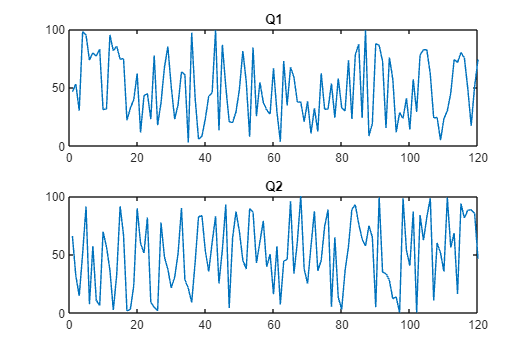

% Plot Q1 and Q2
% Select columns Q1 and Q2
data_q = data(:,{'Q1','Q2'});

% Create separate subplots for Q1 and Q2
figure('Position', [100, 100, 1200, 800]);
subplot(2,1,1)
plot(data_q.Q1)
title('Q1')
subplot(2,1,2)
plot(data_q.Q2)
title('Q2')

**Boxplot, Density Plot, Scatter Plot**

**Boxplot: **A boxplot display works well when you want to see the distribution of the data. They show the median, first quartile, and third quartile values, along with outliers. The box spans the interquartile range, which is the first quartile value to the third quartile value. The median is represented by a line inside of the box. All other points, except outliers, are inside of the brackets around the box.

**Density Plot: **Density plots are good for seeing concentrations in data. They plot the range of values being analyzed on the x-axis and probability density on the y-axis, making them a continuous version of a histogram. With density plots you can see what values are most and least likely to occur and whether the data is normally distributed or not. 

**Scatter Plot: **Scatter plots are good for seeing data trends. They plot a dependent variable versus an independent one without lines connecting the data points. The data can then be analyzed to see if any trend exists. 

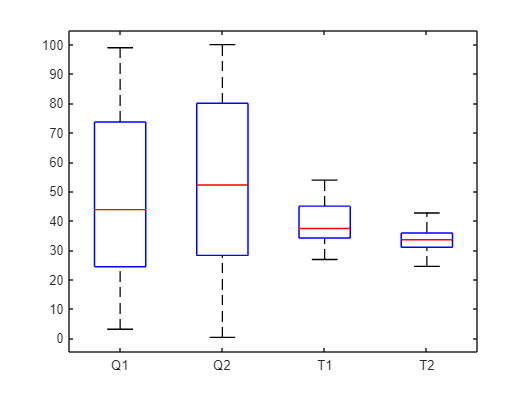

% Create a Boxplot
figure;
boxplot(A,'Labels',data.Properties.VariableNames)

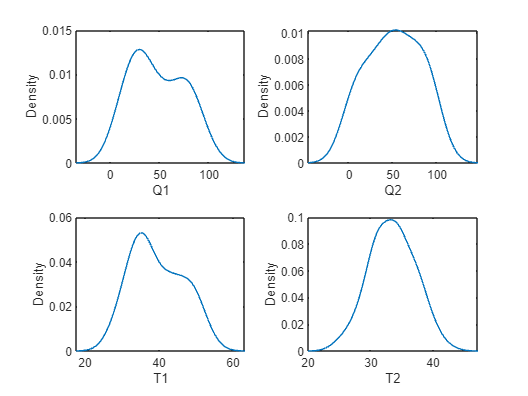


% Density plot
subplot(2,2,1)
ksdensity(table2array(data(:,"Q1")))
xlabel('Q1')
ylabel('Density')
subplot(2,2,2)
ksdensity(table2array(data(:,"Q2")))
xlabel('Q2')
ylabel('Density')
subplot(2,2,3)
ksdensity(table2array(data(:,"T1")))
xlabel('T1')
ylabel('Density')
subplot(2,2,4)
ksdensity(table2array(data(:,"T2")))
xlabel('T2')
ylabel('Density')

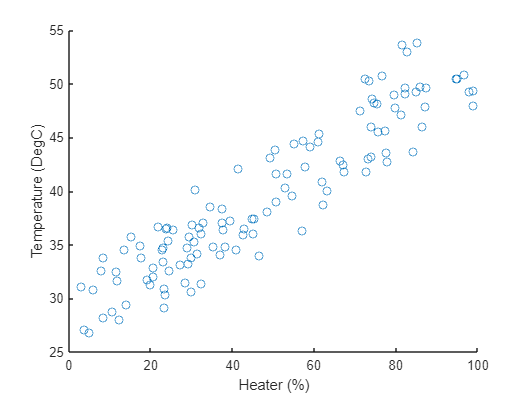


% Scatter Plot
figure;
scatter(data,"Q1","T1")
xlabel('Heater (%)')
ylabel('Temperature (DegC)')

These plots give information on the general trend of the data. It is three different ways to view the same information.

**Pairplot**

**Pairplot: **Pairplots are a graphical matrices made by plotting each variable against every other variable. They are good for exploring relationships between variables in a dataset and identifying potential patterns or trends. 

This pairplot compares the correlations between the two temperatures and the heaters.

% Pair Plot
figure;
label = {'Q1','Q2','T1','T2'};
[~,AX]=plotmatrix(A)

AX =   4×4 Axes array:

    Axes    Axes    Axes    Axes
    Axes    Axes    Axes    Axes
    Axes    Axes    Axes    Axes
    Axes    Axes    Axes    Axes


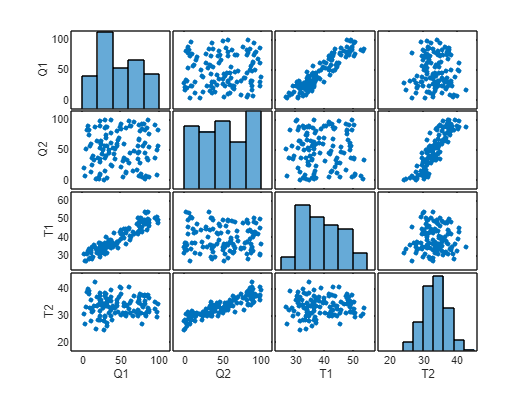

ylabel(AX(1,1),'Q1')
ylabel(AX(2,1),'Q2')
ylabel(AX(3,1),'T1')
ylabel(AX(4,1),'T2')
xlabel(AX(4,1),'Q1')
xlabel(AX(4,2),'Q2')
xlabel(AX(4,3),'T1')
xlabel(AX(4,4),'T2')

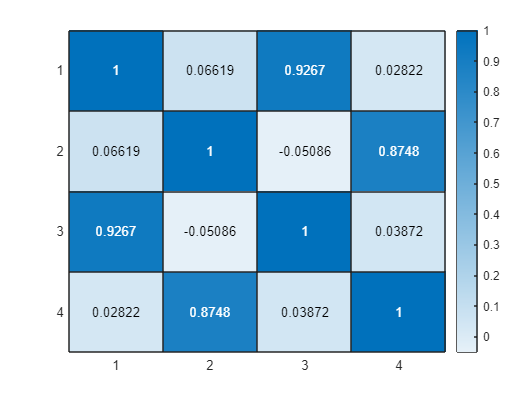


% Heatmap
correlation = corrcoef(table2array(data));
figure;
heatmap(correlation)

## Activity

Explore data from [PVWatts](https://pvwatts.nrel.gov/) for BYU South Campus. PVWatts is a package from NREL to estimate the energy production and cost of energy of grid-connected photovoltaic (PV) energy systems. Investigate the specific data columns as **factors** listed below from all of the potential data factors.

Answer the following questions:

- What factors are highly correlated with DC Array Output (W)?

- What factors are highly correlated with Cell Temperature (C)?

- PV cells are more efficient at lower temperatures. Does the data also show this effect? Why or why not?

% Import data
url='http://apmonitor.com/pds/uploads/Main/PV_BYU_South.txt';
df = readtable(url,'VariableNamingRule','preserve')

df = 8760×11 table
    Month    Day    Hour    Beam Irradiance (W/m^2)    Diffuse Irradiance (W/m^2)    Ambient Temperature (C)    Wind Speed (m/s)    Plane of Array Irradiance (W/m^2)    Cell Temperature (C)    DC Array Output (W)    AC System Output (W)
    _____    ___    ____    _______________________    __________________________    _______________________    ________________    _________________________________    ____________________    ___________________    ____________________

      1       1       0                 0                           0                          -1                      4            

columns = df.Properties.VariableNames;
disp(columns)

    {'Month'}    {'Day'}    {'Hour'}    {'Beam Irradiance (W/m^2)'}    {'Diffuse Irradiance (W/m^2)'}    {'Ambient Temperature (C)'}    {'Wind Speed (m/s)'}    {'Plane of Array Irradiance (W/m^2)'}    {'Cell Temperature (C)'}    {'DC Array Output (W)'}    {'AC System Output (W)'}



factors=["Ambient Temperature (C)"; 
         "Wind Speed (m/s)";
         "Plane of Array Irradiance (W/m^2)";
         "Cell Temperature (C)"; 
         "DC Array Output (W)"]

factors = 5×1 string array
    "Ambient Temperature (C)"
    "Wind Speed (m/s)"
    "Plane of Array Irradiance (W/m^2)"
    "Cell Temperature (C)"
    "DC Array Output (W)"


data = df(:,factors)

data = 8760×5 table
    Ambient Temperature (C)    Wind Speed (m/s)    Plane of Array Irradiance (W/m^2)    Cell Temperature (C)    DC Array Output (W)
    _______________________    ________________    _________________________________    ____________________    ___________________

              -1                      4                              0                             -1                      0       
              -1                      3                              0                             -1                      0       
              -3                      2                              0                             -3                      0       
              -4                      2                              0                             -4                      0       
              -5 

mask = data.("Plane of Array Irradiance (W/m^2)")>0.01;
data = data(mask,:)

data = 4341×5 table
    Ambient Temperature (C)    Wind Speed (m/s)    Plane of Array Irradiance (W/m^2)    Cell Temperature (C)    DC Array Output (W)
    _______________________    ________________    _________________________________    ____________________    ___________________

              -5                      1                         22.761                         -7.147                 90.046       
              -3                      1                         74.198                          -3.16                 288.75       
              -1                      1                         130.15                          1.139                 497.11       
               0                      1                         730.17                          21.83                 2517.7       
               0 

data.('efficiency') = data.("DC Array Output (W)")./data.("Plane of Array Irradiance (W/m^2)")

data = 4341×6 table
    Ambient Temperature (C)    Wind Speed (m/s)    Plane of Array Irradiance (W/m^2)    Cell Temperature (C)    DC Array Output (W)    efficiency
    _______________________    ________________    _________________________________    ____________________    ___________________    __________

              -5                      1                         22.761                         -7.147                 90.046             3.9562  
              -3                      1                         74.198                          -3.16                 288.75             3.8917  
              -1                      1                         130.15                          1.139                 497.11             3.8195  
               0                      1      


% Summary of statistics
summary(data)

Variables:

    Ambient Temperature (C): 4341×1 double

        Values:

            Min         -18   
            Median       11   
            Max          35   

    Wind Speed (m/s): 4341×1 double

        Values:

            Min           0   
            Median        2   
            Max          10   

    Plane of Array Irradiance (W/m^2): 4341×1 double

        Values:

            Min         0.944 
            Median     410.33 
            Max        1120.3 

    Cell Temperature (C): 4341×1 double

        Values:

            Min       -16.699 
            Median     22.767 
            Max        66.337 

    DC Array Output (W): 4341×1 double

        Values:

            Min         3.261 
            Median     1386.7 
            Max        3709.3 

    efficiency: 4341×1 double

        Values:

            Min        2.2826 
            Median     3.3213 
     


% Calculate the mean
factors =  ["Ambient Temperature (C)";
         "Wind Speed (m/s)";
         "Plane of Array Irradiance (W/m^2)";
         "Cell Temperature (C)";
         "DC Array Output (W)";
         "efficiency"]

factors = 6×1 string array
    "Ambient Temperature (C)"
    "Wind Speed (m/s)"
    "Plane of Array Irradiance (W/m^2)"
    "Cell Temperature (C)"
    "DC Array Output (W)"
    "efficiency"


descr = varfun(@mean,data,"InputVariables",factors);
disp(descr)

    mean_Ambient Temperature (C)    mean_Wind Speed (m/s)    mean_Plane of Array Irradiance (W/m^2)    mean_Cell Temperature (C)    mean_DC Array Output (W)    mean_efficiency
    ____________________________    _____________________    ______________________________________    _________________________    ________________________    _______________

               11.989                      1.7664                            452.51                             24.155                       1459.2                 3.3241     




% Calculate standard deviation
descr = varfun(@std,data,"InputVariables",factors);
disp(descr)

    std_Ambient Temperature (C)    std_Wind Speed (m/s)    std_Plane of Array Irradiance (W/m^2)    std_Cell Temperature (C)    std_DC Array Output (W)    std_efficiency
    ___________________________    ____________________    _____________________________________    ________________________    _______________________    ______________

              10.982                      1.279                           335.21                             17.233                     1047.7                0.32374    




% Calculate Quartiles
A = table2array(data);
table1 = array2table(quantile(A,[0.25,0.5,0.75]),'VariableNames',factors);
table1.Properties.RowNames = ["25%","50%","75%"]

table1 = 3×6 table
           Ambient Temperature (C)    Wind Speed (m/s)    Plane of Array Irradiance (W/m^2)    Cell Temperature (C)    DC Array Output (W)    efficiency
           _______________________    ________________    _________________________________    ____________________    ___________________    __________

    25%               2                      1                         134.23                         10.219                 448.89             3.0832  
    50%              11                      2                         410.33                         22.767                 1386.7             3.3213  
    75%              22                      2                         746.05                         37.515     

descr = varfun(@std,data,"InputVariables",factors);
disp(descr)

    std_Ambient Temperature (C)    std_Wind Speed (m/s)    std_Plane of Array Irradiance (W/m^2)    std_Cell Temperature (C)    std_DC Array Output (W)    std_efficiency
    ___________________________    ____________________    _____________________________________    ________________________    _______________________    ______________

              10.982                      1.279                           335.21                             17.233                     1047.7                0.32374    



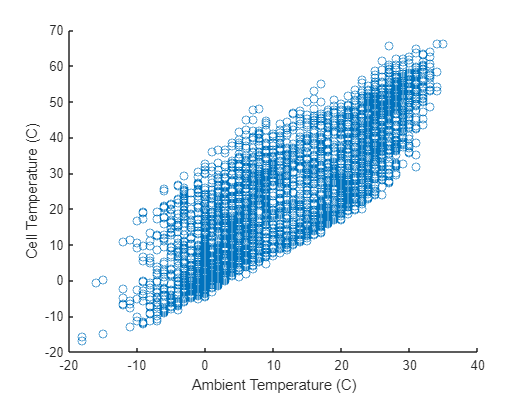

scatter(data.("Ambient Temperature (C)"),data.("Cell Temperature (C)"))
xlabel("Ambient Temperature (C)")
ylabel("Cell Temperature (C)")

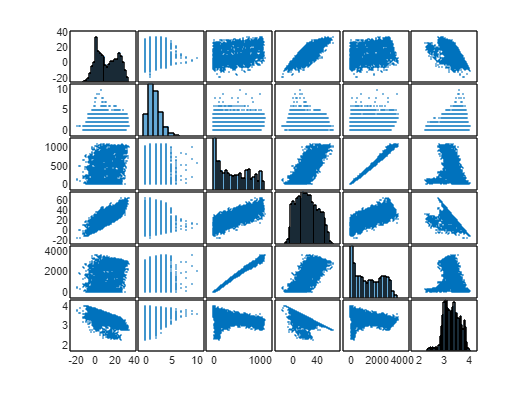

plotmatrix(table2array(data))

**Activity Answers**

- DC array output has a high positive correlation with cell temperature and plane of array irradiance. 

- Cell temperature has a high positive correlation with ambient temperature, plane of irradiance, and DC array output. It has a negative correlation with efficiency.

- Yes, the data shows this effect and it is apparent in the plot matrix. You can see that the highest efficencies occur when the cell temperauture is low. 

**Further Practice**

Coetsee, R. [**MATLAB data processing and visualization**](https://matlabacademy.mathworks.com/details/matlab-for-data-processing-and-visualization/mlvi)

MathWorks, Inc. [**MATLAB Plot Gallery**](https://www.mathworks.com/products/matlab/plot-gallery.html)